#### input transfer function


syms s
  try
    sys= input("please enter your transfer funtion .. ex. (1)/((s^2+s+1)) ;;\n DONT FORGET THE BRACKETS ^>^:")
    [num,den]=numden(sys);
    den_coef=sym2poly(den);
    if sys==0 || sys ==inf
        den_coef=[];
        error('Please Enter a NON ZERO transfer function numerator or denominator')
    end
   
    while den_coef(1)~= 0
        if den_coef(1)==0
           den_coef(1)=[];
          
        end
    end
    den_coef
  catch
      warning("PLEASE ENTER A VALID TRANSFER FUNCTION")
  end

$$sys = \frac{1}{s^{2}+s+1}$$


%make rowth table
first_row=den_coef(1:2:end)

first_row =      1     1


second_row=den_coef(2:2:end);
maxlen=max(length(first_row));
second_row(end+1:maxlen)=0;
if second_row(1)==0
    second_row(1)=[0.0001];
end
second_row

second_row =      1     0


rows=[first_row;second_row]

rows =      1     1
     1     0


    Var1     new_rows
    _____    ________

    "s^2"     1    1 
    "s"       1    0 
    "1"       1    0 

system is stable

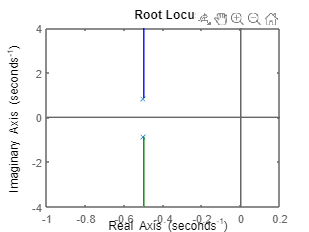

%call RouthCriteria class that caries the logic
routh=RouthCriteria();
routh.rowz=rows;
routh.itterations= length(den_coef);
routh.system=tf(sym2poly(num),den_coef);
routh.generate_rows()